clc 
close all
x1=input("enter a seq:");
N=input("enter the points");
M=zeros(N,N);
for k=0:N-1
    for n=0:N-1
        M(k+1,n+1)=exp(1i*2*pi*n*k/N)/N;
    end
end
L=length(x1);
if L<=N
    x=[x1 zeros(1,(N-L))];
end
x2=zeros(N,1);
Xk=M*x.'

Xk =   -4.0000 + 0.0000i
  -3.0000 + 0.0000i
  -2.0000 - 0.0000i
  -1.0000 - 0.0000i


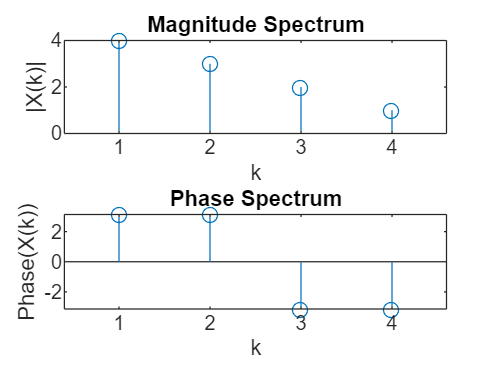

k=1:1:N;

subplot(2,1,1)
stem(k, abs(Xk))
title('Magnitude Spectrum')
xlabel('k')
ylabel('|X(k)|')
subplot(2,1,2)
stem(k, angle(Xk))
title('Phase Spectrum')
xlabel('k')
ylabel('Phase(X(k))')